# Analiza mowy w dziedzinie czasu

## Detekcja aktywności głosowej

Pierwszym krokiem większości algorytmów analizujących mowę jest detekcja momentów, w których mowa w ogóle występuje w nagraniu. Spośród wielu metod najprostsza jest analiza energii sygnału. Licząc chwilową energię dla zadanego fragmentu wg wzoru $\textrm{STE}=\sum_{i=1}^k x_i^2$ bądź w wersji $\textrm{RMS}=\sqrt{\sum_{i=1}^k x_i^2 }$. Długość okna powinna być dobrana tak, żeby nie wyciąć z sygnału fragmentów posiadających naturalnie niską energię (przejść pomiędzy głoskami). W przykładzie poniżej ustawione jest okno 200 ms.

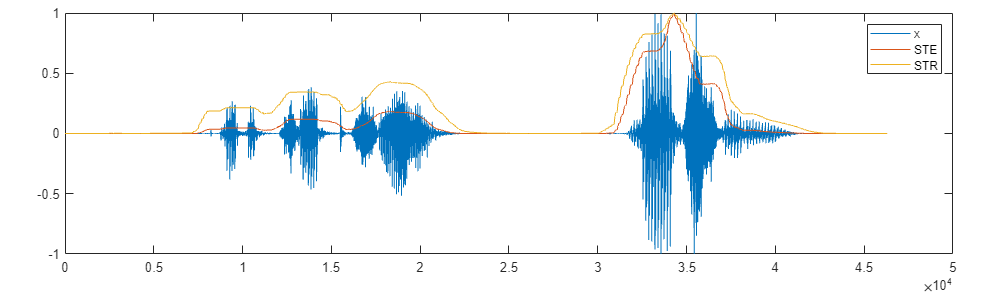

% wczytanie i normalizacja nagrania
[x, fs] = audioread("percepcja.wav");

x = x - mean(x);
x = x / max(x);

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;

plot(x);
ylim([-1 1]);

% długość okna analizy: 200 ms
win = round(fs * 0.2);

% energia chwilowa
ste = conv(x.^2, ones(1,win), 'same');
ste = ste / max(ste);

% wersja z pierwiastkiem
str = sqrt(ste);

hold on;
plot(ste);
plot(str);

legend("x", "STE", "STR");

Dokonując progowania wyznaczonych miar energii wyznaczamy fragmenty nagrania, gdzie obecna jest aktywność głosowa. Podobnie jak przy wyborze wielkości okna, staramy się uniknąć podziały sugnału w środku słów.

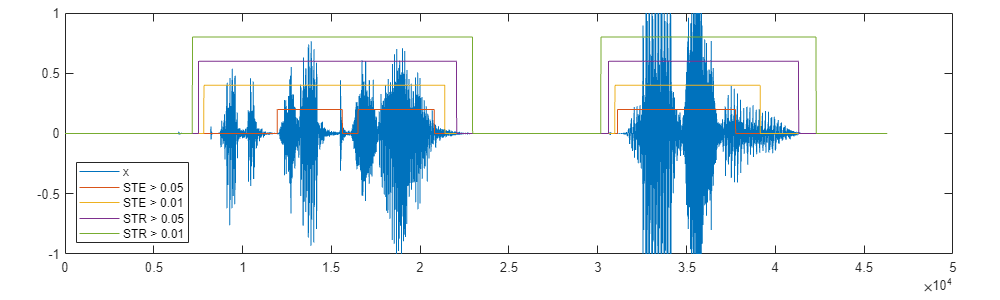

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(2*x);
ylim([-1 1]);
hold on;
plot(0.2 * (ste > 0.05));
plot(0.4 * (ste > 0.02));
plot(0.6 * (str > 0.05));
plot(0.8 * (str > 0.01));
legend("x", "STE > 0.05", "STE > 0.01", "STR > 0.05", "STR > 0.01", "Location", "southwest");

## Klasyfikacja fragmentów na dźwięczne i bezdźwięczne

### Analiza sygnału

Głoski w mowie można podzielić zgrubnie na dźwięczne (w szczególności są to samogłoski, ale nie tylko) i bezdźwięczne (takie jak s, f, h, ...). Spójrzmy na wykres dwóch przykładowych głosek:

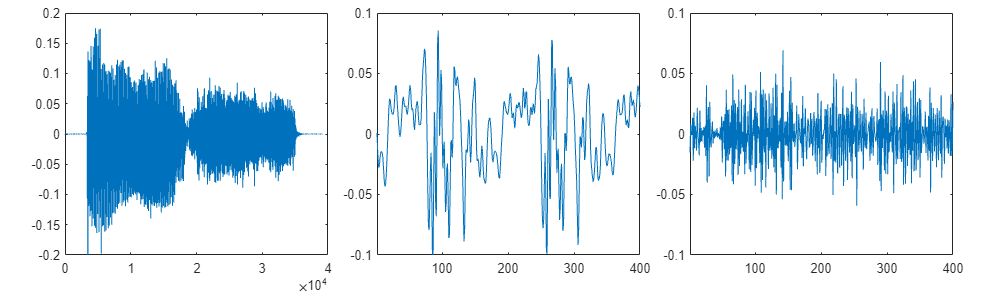

[x, fs] = audioread("es.wav");

win = round(fs * 0.025);

figure("Position", [0 0 1000 300]);
tiledlayout(1,3,'TileSpacing','Compact','Padding','Compact');

% cały sygnał
nexttile
plot(x);
ylim([-0.2 0.2]);

% fragment E
e_crop = x(10000:10000+win);
nexttile;
plot(e_crop)
xlim([1 win]);
ylim([-0.1 0.1]);

% fragment S
s_crop = x(25000:25000+win);
nexttile;
plot(s_crop);
xlim([1 win]);
ylim([-0.1 0.1]);

Wyraźnie widać różnicę. Fragment dźwięczny jest w miarę okresowy i dużo rzadziej niż bezdźwięczny szum zmienia znak (przechodzi przez zero). Popatrzmy jeszcze na to samo nagranie w dziedzinie częstotliwości:

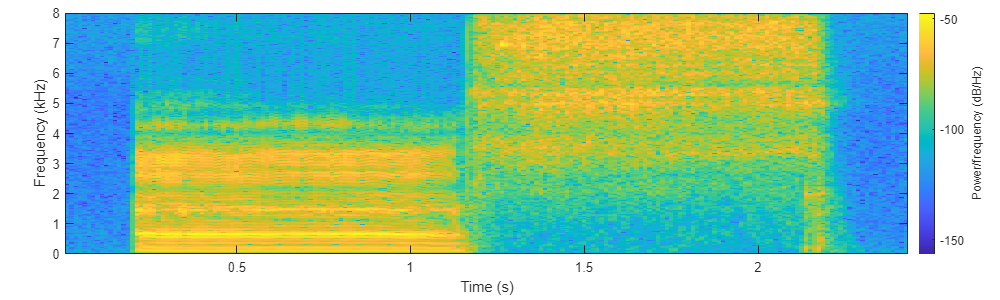

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
spectrogram(x, win, win/2, [], fs, 'yaxis');

### Zliczanie przejść sygnału przez zero

Wartości dla dwóch pokazanych fragmentów:

zerocrossrate(e_crop)

ans = 0.0948

zerocrossrate(s_crop)

ans = 0.7756

Można też wyznaczyć ten sam współczynnik dla całego sygnału:

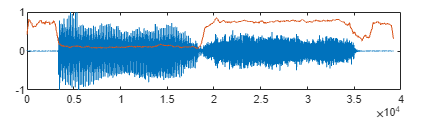

x1 = x;
x2 = [0; x(1:end-1)];
diff = sign(x1) ~= sign(x2);

zcr = conv(diff, ones(1, win) / win, "same");


figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(x / max(x));
ylim([-1 1])
hold on;
plot(zcr);

## Określenie częstotliwości bazowej

Zgodnie z wcześniejszą obserwacją, fragmenty dźwięczne charakteryzują się okresowością sygnału. Pierwsza znacząca częstotliwość, z którą sygnał się powtarza, zwana jest częstotliwością bazową i jest charakterystyczna dla każdej osoby. Dla fragmentu E powyżej okres wynosi ok. 172 próbki, co przy częstotliwości próbkowania 16 kHz daje częstotliwość bazową ok. 93 Hz. Można przyjąć, że F0 powinnabyć poniżej 300 Hz. Z metod wyznaczania tej częstotliwości, poznanych na poprzednich zajęciach, tym razem skorzystamy z autokorelacji. Uwaga: częstotliwość bazowa odpowiada **największemu** pikowi na wykresie autokorelacji, nie pierwszemu. 

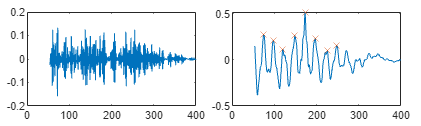

figure("Position", [0 0 1000 300]);
tiledlayout(1,2,'TileSpacing','Compact','Padding','Compact');


f_max = 300;
lag_min = fs / f_max;

nexttile

[c, lags] = xcorr(s_crop, "normalized");
c = c(lags > lag_min);
lags = lags(lags > lag_min);
[pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);

plot(lags, c);
hold on;
plot(lags(loc), pks, "x");

nexttile

[c, lags] = xcorr(e_crop, "normalized");
c = c(lags > lag_min);
lags = lags(lags > lag_min);
[pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);

plot(lags, c);
hold on;
plot(lags(loc), pks, "x");

### Wyznaczenie F0 w oknach sygnału

Uwaga: implementacja funkcji pitchwin jest jednym z zadań, kod nie jest udostępniany.

edit by Tomasz Pawlak - kod jest wrzucony MUJ WŁASNY PRYWATNY, żeby zobaczyć jak to działa

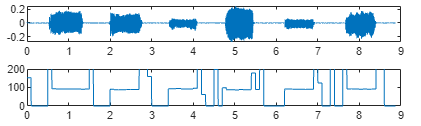

[x, fs] = audioread("aeiouy.wav");

t = linspace(0, length(x)/fs, length(x));
win = round(fs * 0.1);

figure("Position", [0 0 1000 300]);
tiledlayout(2,1,'TileSpacing','Compact','Padding','Compact');

nexttile
plot(t, x);

f0 = pitchwin(x, fs, win);

nexttile;
plot(t, f0);
ylim([0 200]);

I jeszcze wizualizacja na spektrogramie.

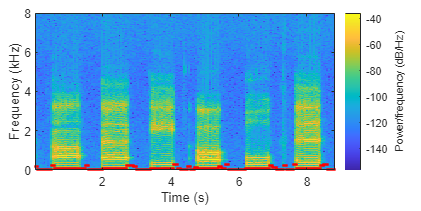

figure("Position", [0 0 1000 500]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');

nexttile

spectrogram(x, win, win/2, [], fs, 'yaxis');
hold on;
plot(t, f0 / 1000, 'r.');

## Funkcje pomocniczne

function zcr = zerocrossrate(x)
    zc = diff(sign(x));
    zcr = sum(zc ~= 0) / length(x);
end
function [lbls] = label(x, fs)
% autor : Tomasz Pawlak
% cel : szufladkowanie ramek sygnału na dźwięczne głoski, niedźwięczne
% głoski oraz szum
%
% x = sygnał spróbkowany częstotliwością fs
%
% inicjacja stałych przydatnych przy analizie podziału głosek
NOT_NOISED_MEAN = 0.05;
STR_THRESHOLD = 0.01;
STE_THRESHOLD = 0.05;
SOUNDNESS_THRESHOLD = 0.2;
% długość okna analizy: 160 klatek
win_len = round(fs * 0.01);

% inicjacja lbls
lbls = -1*ones(length(x),1);

% obliczanie funkcji stosunku sygnał/szum dla sygnału x
ste = conv(x.^2, ones(1,win_len), 'same');
ste = ste / max(ste);
str = sqrt(ste);

% odrzucenie próbek niedźwięcznych - nie chcielibyśmy ich analizować
lbls_active = 1 * (str > STR_THRESHOLD);

% iteracja po ramkach - ostatnia jest ucięta do swojego realnego końca
for i=1:ceil(length(x)/win_len)
    if i*win_len > length(x)
        endpoint = length(x);
    else
        endpoint = i*win_len;
    end

    win = x(win_len*(i-1)+1:endpoint);

    % średnie sound to noise ratio ramki aby poddawać ją analizie
    if mean(lbls_active(win_len*(i-1)+1: endpoint)) > NOT_NOISED_MEAN
        % współczynnik przychodzenia przez zero określa odróżnienie głosek
        % dźwięcznych od bezdźwięcznych
        zcr = zerocrossrate(win);

        % empirycznie ustalony próg dźwięczności celem odróżnienia głosek
        if zcr > SOUNDNESS_THRESHOLD
            lbls(win_len*(i-1)+1: endpoint) = 1;
        else
            lbls(win_len*(i-1)+1: endpoint) = 2;
        end
    else
        lbls(win_len*(i-1)+1: endpoint) = 0;
    end

end
end

function [x_p] = pitchwin(x, fs, win_len)
% autor : Tomasz Pawlak
% cel : wyznaczenie częstotliwości f0 dla ramek próbkowanego sygnału BEZ
% pominięcia głosek bezdźwięcznych oraz ciszy
% schemat działania : 
%   > ramka bez dzwieku -> przypisz "0" 
%   > ramka z dzwiekiem -> przypisz f0 = fs/N;
%   N - indeks ramki gdzie autokorelacja ma największą wartość
% parametry wejściowe :
%   syngał x próbkowany z częstotliwością fs podzielony na ramki o długości
%   win_len (zakładając że ostatnia może być krótsza)

x_p = zeros(length(x),1);

% inicjacja największej dopuszczalnej f0 głosu ludzkiego
f_max = 300;
% inicjacja minimalnego błędu
lag_min = fs / f_max;

% iteracja po ramkach - ostatnia jest ucięta do swojego realnego końca
for i=1:ceil(length(x)/win_len)
    if i*win_len > length(x)
        endpoint = length(x);
    else
        endpoint = i*win_len;
    end
    % ograniczenie sygnału badanego do ramki
    win = x(win_len*(i-1)+1:endpoint);
    % autokorelacja sygnału
    [c, lags] = xcorr(win, "normalized");
    % przycięcie sygnału autokorelowanego i jego indeksów w oknie do
    % wartości spełniających założenia minimalnego odchylenia
    c = c(lags > lag_min);
    lags = lags(lags > lag_min);
    % znalezienie maksymów lokalnych sygnału z założeniem szerokości oraz
    % znaczenia (prominence)
    [pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);
    % znalezienie maksymum globalnego
    max_peak = maxk(pks, 1);
    % inicjacja indeksu, żeby błędami nie sypał
    ind = -1;
    if ~isempty(max_peak)
        % znalezienie indeksu peaku w oknie o najwyższym sygnale
        ind = find(pks==max_peak);
    end
    if ind ~= -1
        % przypisanie odwrotności wartości szczytu o najwyższym sygnale -
        % wymnożone przez częstotliwość próbkowania
        x_p(win_len*(i-1)+1:endpoint) = fs/lags(loc(ind));
    end
end
end
